Program for design of shaft, Problem Number 3.

Problem Statement:A line shaft is transmitting 650 kW of power at 500 rpm and is made of C35 material. The shaft carries a central load of 1,000 N and is simply supported between the bearings 3 m apart. Determine the diameter of the shaft, considering ASME code and steady load for rotating shaft.  

Name: Avva Sai Pranav

USN : PES1201800861

Date : 13/09/2020

clc;
clear all;

Given data :

𝑃 = 650 𝑘𝑊 

n = 500 𝑟𝑝𝑚 

𝐹 = 1,000 𝑁 

𝐿 = 3m = 3 × 10^3m

P = 650

P = 650

n = 500

n = 500

F = 1000

F = 1000

L = 10^3

L = 1000

Initalizing the Ulimate and endurance stress. Also finding the max stress respectively using ASME  standards.

S_u = 510;
S_e = 304;
S_max1 = 0.6*S_e;
S_max2 = 0.36*S_u;

Finding the lower values and setting it as the max shear stress.

if S_max1 < S_max2
    S_max = S_max1
else
    S_max = S_max2
end

S_max = 182.4000

Finding the maximum tau value, and setting the lower tau values.

Tu_max1 = 0.3*S_e;
Tu_max2 = 0.18*S_u;
if Tu_max1 < Tu_max2
    Tu_max = Tu_max1
else
    Tu_max = Tu_max2
end

Tu_max = 91.2000

Finding the torque value.

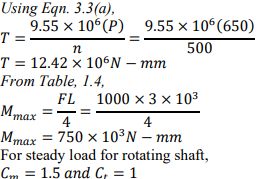

T = Eqn_3_3_a(P,n)

T = 12415000

M_max = (F*L)/4

M_max = 250000

For steady load for rotating shaft,

Cm = 1.5;
Ct = 1;

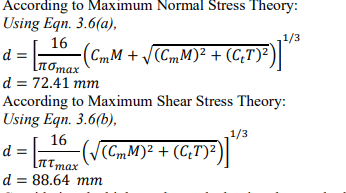

[d_n, d_s] = Eqn_3_6(S_max,Tu_max,M_max,T,Cm,Ct)

d_n = 70.9582

d_s = 88.5197

Finding the larger value of diameter from the 2 stress theories.

if d_n > d_s
    d = d_n
else
    d = d_s
end

d = 88.5197

Finding the standard diameter from table 3.5a

d = Table_3_5_a(d)

Standard size of the shaft (mm) using table 3.5(a) is : 


d = 90

d = 90

disp('Shear Stress (N/mm^2) induced on the shaft is : ')

Shear Stress (N/mm^2) induced on the shaft is : 


Tu = Eqn_3_1(T,d);